# Normal and shear stresses on faults

These examples are stolen and modified without remorse from N. Espinoza ([https://dnicolasespinoza.github.io/node38.html#fig:3DMohrCircle](https://dnicolasespinoza.github.io/node38.html#fig:3DMohrCircle)).

### Geographic coordinate system

For the geographical considerations below we introduce the N-E-D geographic coordinate system $\{\mathbf{e}_i\}$:

$\mathbf{e}_1$= North, $\mathbf{e}_2$= East, $\mathbf{e}_3$= Down 

This system is right handed.

e1 = [1;0;0]; e2 = [0;1;0]; e3 = [0;0;1];

Note that $\mathbf{e}_3$ is not '-1', because the third axis is pointing down.

### Geological description of a fault plane

In geology we describe a fault orientation by two measures the dip and the strike as illustrated in the figure below. The strike of a plane is its intersection with a horizontal plane and it is typicaly given by measuring its azimuth, i.e., angle from North on a map. The dip is the angle of a plane with the horizontal, or equivalently the angle between the normal of the surface and the vertical.

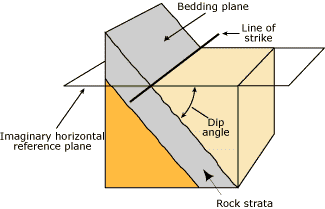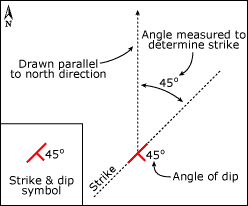

These figure are taken from this website [[link](https://college.cengage.com/geology/resources/protected/physicallab/thelab/geologicmaps/activities/activity1/activity1.htm)]. (Congratulations, you're on your way to becoming a beologist.)

## Example 1:

### Fault orientation

Here we consider a particularly simple fault orientation:

- strike azimuth = 0 deg, 

- dip angle = 60 deg

dip = deg2rad(60);

The normal to the fault plane in the geographic frame $\{\mathbf{e}_i\}$ is given by

n = [0;cos(pi/2-dip);-sin(pi/2-dip)];

### State of stress: 

In geology one of the principal stresses is often (near) vertical, $\sigma_v$. The other two principla directions must therefore be in the horizontal plane. They are therefore often referred to as the minimum horizontal stress, $\sigma_h$, and the maximum horizontal stress, $\sigma_H$. In this example we consider the following simple stress state.

- $\sigma_1=\sigma_v=23$ MPa , $\mathbf{e}'_1=\mathbf{e}_3$ (vertical)

- $\sigma_3=\sigma_h=13.8$ MPa, $\mathbf{e}'_3=\mathbf{e}_2$ (azimuth = 90, East)

- $\sigma_2=20$ MPa, $\mathbf{e}'_2 = \mathbf{e}'_3\times\mathbf{e}'_1$ (cyclic permutation $\Rightarrow$ right handed)

where we refer to the frame of the principal directions of the stress tensor as the primed frame$\{\mathbf{e}'_i\}$ and express the basis vector in terms of the unprimed geographic coordinate system.

ep1 = e3;
ep3 = e2;
ep2 = cross(ep3,ep1)

ep2 =      1
     0
     0


cross(ep1,ep2)'*ep3 % check right-handedness

ans = 1

The stress tensor in the principal frame $\{\mathbf{e}'_i\}$is

sig_1 = 23; sig_2  = 20; sig_3 = 13.8; p = 0; % MPa
sigma_p = [sig_1     0       0;...
             0     sig_2     0;...
             0       0     sig_3]

sigma_p =    23.0000         0         0
         0   20.0000         0
         0         0   13.8000


Given the basis vectors in the two reference frames $\{\mathbf{e}_i\}$and $\{\mathbf{e}'_i\}$, we can easily compute the change of basis matrix with components $A_{ij} = \mathbf{e}_i\cdot\mathbf{e}'_j$, so that

A = [e1'*ep1 e1'*ep2 e1'*ep3;...
     e2'*ep1 e2'*ep2 e2'*ep3;...
     e3'*ep1 e3'*ep2 e3'*ep3]

A =      0     1     0
     0     0     1
     1     0     0


At this point it is helpful to check that $\mathbf{A}$ is actually a rotation matrix with the properties:

- 
$$\mathbf{A}^T\mathbf{A} =\mathbf{A}\mathbf{A}^T = \mathbf{I}$$


- 
$$\det(\mathbf{A}) = 1$$


det(A) % check rotation matrix 

ans = 1

 A'*A   % Check orthogonality

ans =      1     0     0
     0     1     0
     0     0     1


 A*A'

ans =      1     0     0
     0     1     0
     0     0     1


Once this is established, we can compute the stress tensor in the geographic frame $\{\mathbf{e}_i\}$ with the 

 sigma = A*sigma_p*A'

sigma =    20.0000         0         0
         0   13.8000         0
         0         0   23.0000


Note, all that has happend is that the order of the entries along the diagonal has changed.

### Traction, normal and shear stress

The traction on the fault is:

 tn = sigma*n

tn =          0
   11.9512
  -11.5000


The normal stress is :

 tn_parallel = (n'*tn)*n;
 sig_n = n'*tn % [MPa]

sig_n = 16.1000

The shear stress is:

 tn_perp = tn - tn_parallel; 
 tau = norm(tn_perp)

tau = 3.9837

### Mohr circle

Given the quasi-2D nature of this problem we can calculate the normal and shear stress directly using expressions for Mohr circle.

- 
$$\sigma_n = \frac{\sigma_1+\sigma_3}{2}+\frac{\sigma_1-\sigma_3}{2}\cos(2\theta)$$


- 
$$\tau = \frac{\sigma_1-\sigma_3}{2}\sin(2\theta)$$


We need to identify the angle $\theta$, which is the dip of the fault plane in this case.

 theta = deg2rad(60);
 norm_fault = (sig_1+sig_3)/2+(sig_1-sig_3)/2*cos(2*theta)

norm_fault = 16.1000

 tau_fault = (sig_1-sig_3)/2*sin(2*theta)

tau_fault = 3.9837

Clearly this is the simple method in this case, but the tensor approach also works for the general case (azimuth of the strike not zero) and prinzipal stresses not aligned with the cardinal directions (North, South, East, West). Either weay we should plot the Mohr circle for good measure.

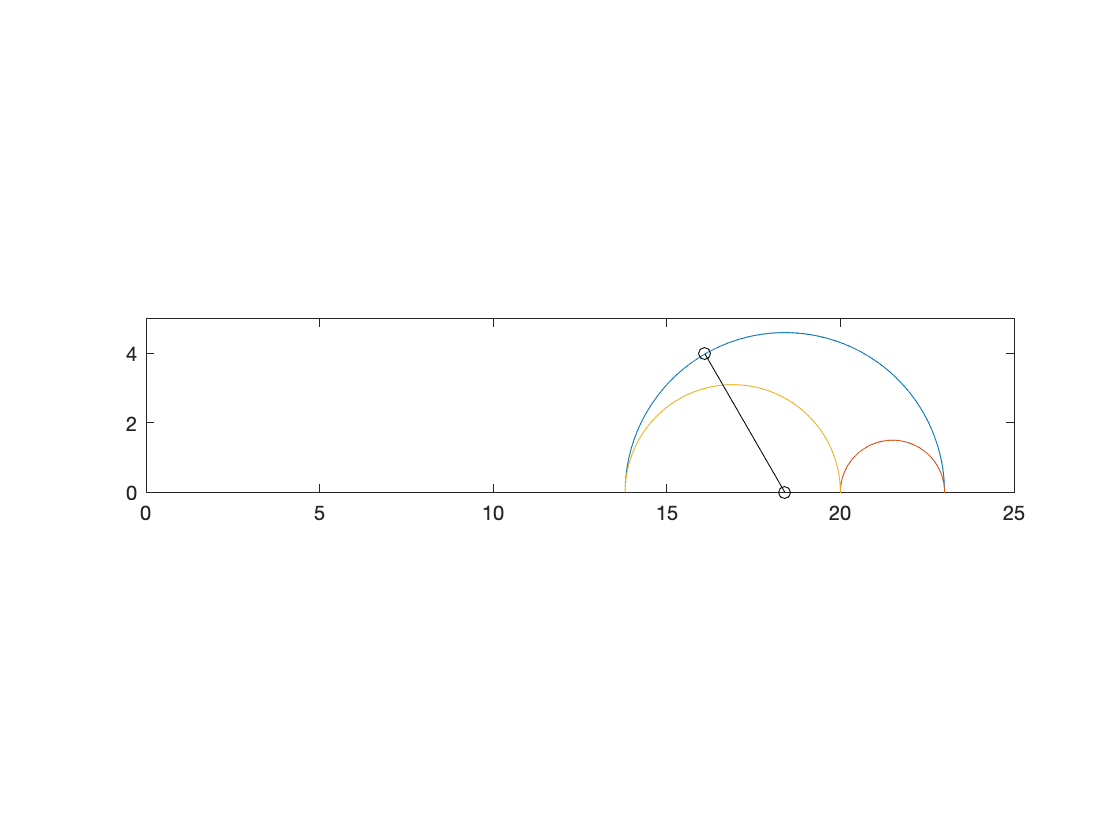

 theta_circ = linspace(0,pi/2,100);
 sig13mean = (sig_1+sig_3)/2;
 tau13 = (sig_1-sig_3)/2*sin(2*theta_circ);
 sig13 = sig13mean+(sig_1-sig_3)/2*cos(2*theta_circ);
 
 tau12 = (sig_1-sig_2)/2*sin(2*theta_circ);
 sig12 = (sig_1+sig_2)/2+(sig_1-sig_2)/2*cos(2*theta_circ);
 
 tau23 = (sig_2-sig_3)/2*sin(2*theta_circ);
 sig23 = (sig_2+sig_3)/2+(sig_2-sig_3)/2*cos(2*theta_circ);
 
 figure
 plot(sig13,tau13), hold on
 plot(sig12,tau12)
 plot(sig23,tau23)
 plot([sig13mean norm_fault],[0 tau_fault],'ko-')
 axis equal
 xlim([0 25]), ylim([0 5])